alpha = 0.1;
beta = 0.001;
gamma = 1;
n = 10000

n = 10000


%E = @(p) gamma*n./(gamma*n + p.*(alpha*log2(p)) + beta*n);
S = @(p) gamma*n./(gamma*n./p + alpha*log2(p) + beta*n)

S = function_handle with value:
    @(p)gamma*n./(gamma*n./p+alpha*log2(p)+beta*n)



E = @(p) S(p)./p

E = function_handle with value:
    @(p)S(p)./p



nproc = [1 2 4 8 16 32 64 128];
S(1)

ans = 0.9990

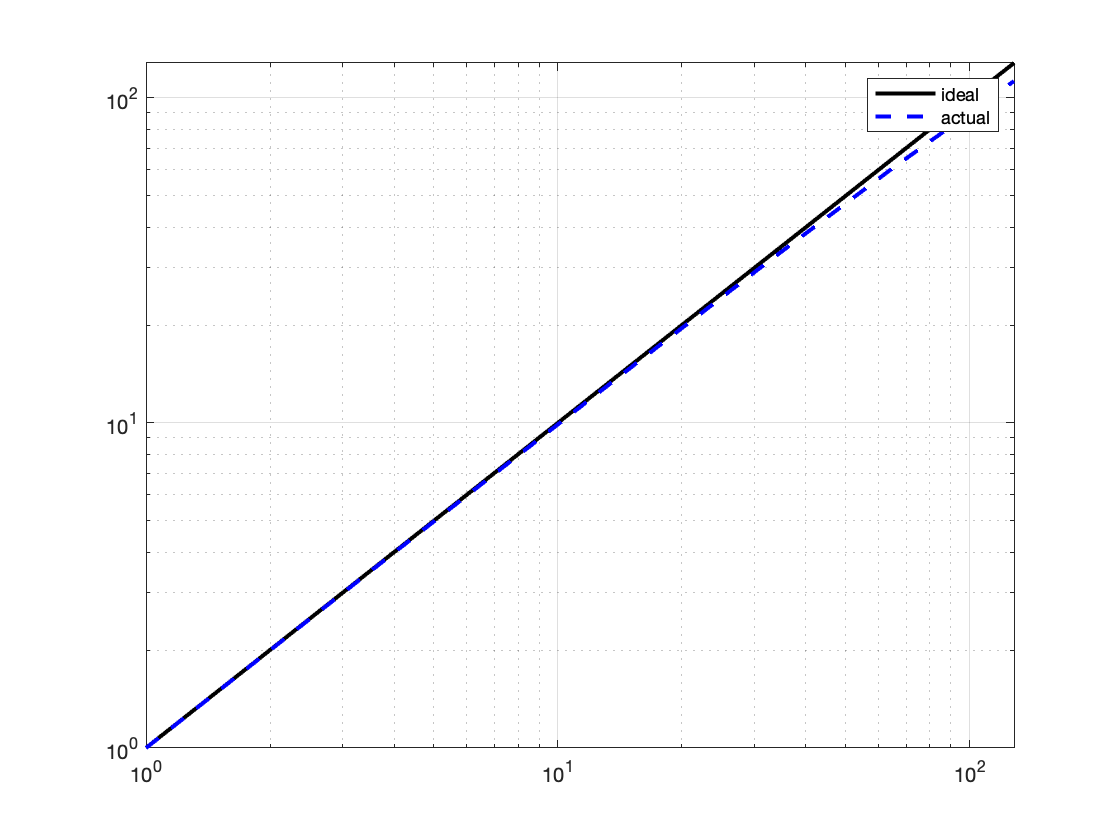


loglog(nproc,nproc,'k',nproc,S(nproc),'--b','LineWidth',2)
grid on;
legend('ideal','actual')

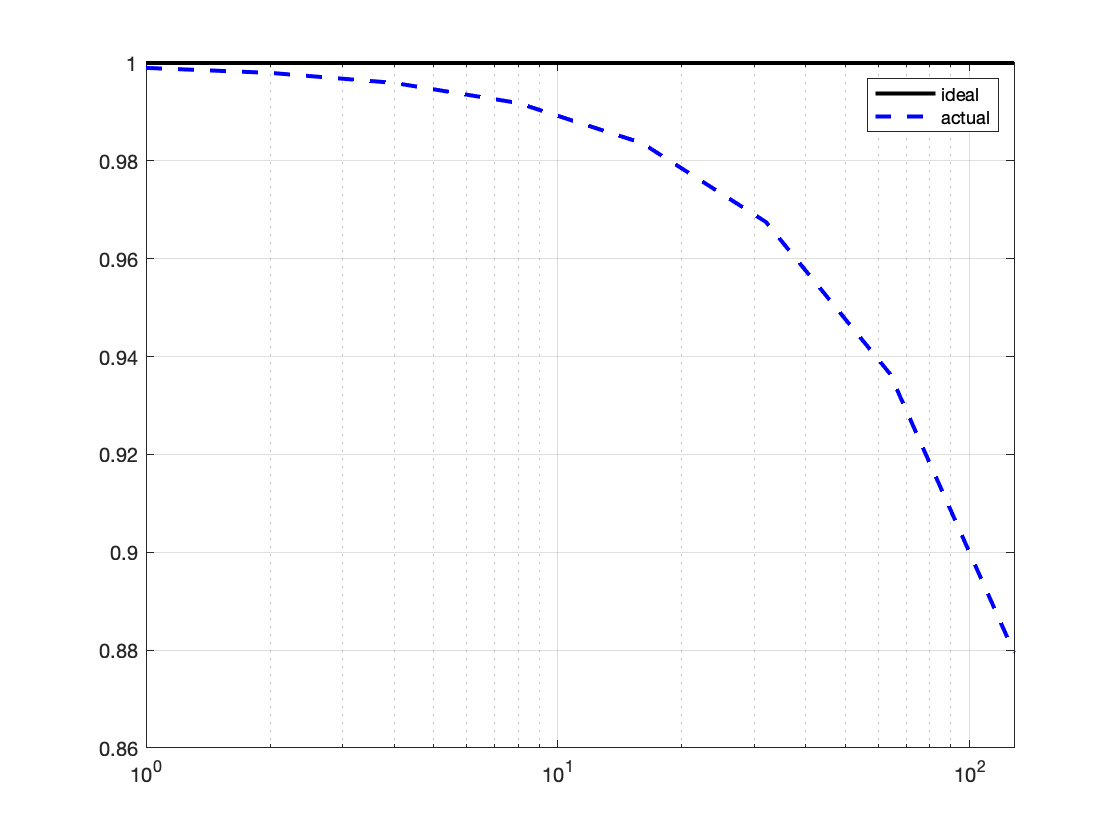

semilogx(nproc,ones(size(nproc)),'k',nproc,E(nproc),'--b','LineWidth',2)
grid on;
legend('ideal','actual')

%ylim([0 1])